# Run analyzePRF on an example dataset to fit the whole time series

clear; close all; setup;

## Load in the data

% Load in the data
load('exampledataset.mat');

% Check the workspace
whos

  Name          Size               Bytes  Class    Attributes

  data          1x4                24448  cell               
  source        1x2                  416  cell               
  stimulus      1x4             48000448  cell               



## Inspect the data

% Check dimensionality of the data
data

data = 1×4 cell array
    {10×150 single}    {10×150 single}    {10×150 single}    {10×150 single}


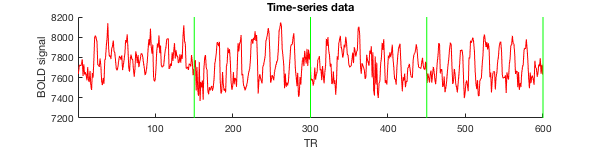

% There are four runs of data; each run consists of 150 time points (TR = 2 s).
% The data have already been pre-processed for slice timing correction, motion
% correction, and spatial undistortion.  For simplicity, we have selected
% 10 example voxels from the left hemisphere.  Let's visualize the time-series
% data for the second voxel.
temp = cellfun(@(x) x(2,:),data,'UniformOutput',0);
figure; hold on;
set(gcf,'Units','points','Position',[100 100 600 150]);
plot(cat(2,temp{:}),'r-');
straightline(150*(1:4)+.5,'v','g-');
xlabel('TR');
ylabel('BOLD signal');
ax = axis;
axis([.5 600+.5 ax(3:4)]);
title('Time-series data');

## Inspect the stimuli

% Check dimensionality of the stimuli
stimulus

stimulus = 1×4 cell array
    {100×100×300 single}    {100×100×300 single}    {100×100×300 single}    {100×100×300 single}


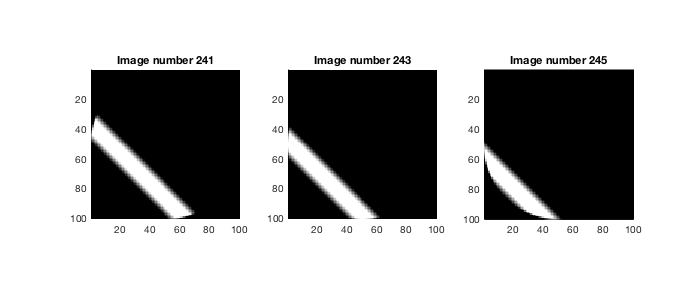

% The stimulus images have been prepared at a resolution of 100 pixels x 100 pixels.
% There are 300 images per run because we have prepared the images at a time resolution
% of 1 second.  (Note that this is faster than the data sampling rate.  When analyzing
% the data, we will resample the data to match the stimulus rate.)  Let's inspect a
% few of the stimulus images in the first run.
figure;
set(gcf,'Units','points','Position',[100 100 700 300]);
for p=1:3
    subplot(1,3,p); hold on;
    num = 239+2*p;
    imagesc(stimulus{1}(:,:,num),[0 1]);
    axis image tight;
    set(gca,'YDir','reverse');
    colormap(gray);
    title(sprintf('Image number %d',num));
end

% Notice that the range of values is 0 to 1 (0 indicates that the gray background was
% present; 1 indicates that the stimulus was present).  For these stimulus images,
% the stimulus is a bar that moves downward and to the left.

## Analyze the data

% We need to resample the data to match the temporal rate of the stimulus.  Here we use
% cubic interpolation to increase the rate of the data from 2 seconds to 1 second (note
% that the first time point is preserved and the total data duration stays the same).
data = tseriesinterp(data,2,1,2);

% Finally, we analyze the data using analyzePRF.  The third argument is the TR, which
% is now 1 second.  The default analysis strategy involves two generic initial seeds
% and an initial seed that is computed by performing a grid search.  This last seed is
% a little costly to compute, so to save time, we set 'seedmode' to [0 1] which means
% to just use the two generic initial seeds.  We suppress command-window output by
% setting 'display' to 'off'.
results = analyzePRF(stimulus,data,1,struct('seedmode',[0 1],'display','off'));

*** analyzePRF: started at 28-Apr-2018 14:56:27. ***


using the following maximum polynomial degrees: [3 3 3 3]
*** fitnonlinearmodel: started at 28-Apr-2018 14:56:28. ***
*** fitnonlinearmodel: loading data. ***
*** fitnonlinearmodel: outputdir = , chunksize = 10, chunknum = 1
*** fitnonlinearmodel: processing voxel 1 (1 of 10). ***
*** fitnonlinearmodel: processing voxel 3 (3 of 10). ***
  starting resampling case 1 of 1.
    trying seed 1 of 2.
      for model 1 of 2, the seed is [50.500 50.500 17.678 10.000 0.500 ].
  starting resampling case 1 of 1.
    trying seed 1 of 2.
      for model 1 of 2, the seed is [50.500 50.500 17.678 10.000 0.500 ].
      the estimated parameters are [83.774 65.728 11.197 15.554 0.500 ].
      for model 2 of 2, the seed is [83.774 65.728 11.197 15.554 0.500 ].
      the estimated parameters are [83.774 65.728 11.197 15.554 0.500 ].
    trying seed 2 of 2.
      for model 1 of 2, the seed is [50.500 50.500 1.768 10.000 0.500 ].
      the estimated parameters are [71.912 60.022 1.262 11.930 0.500 ].
      

% Note that because of the use of parfor, the command-window output for different
% voxels may come in at different times (and so the text above is not really
% readable).

## Inspect the results

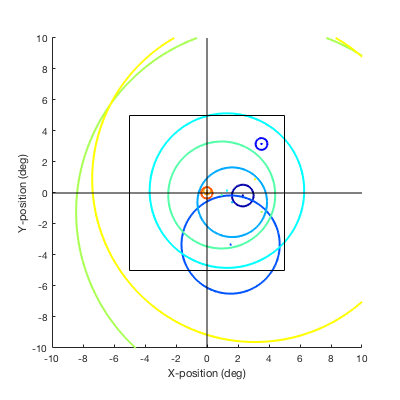

% The stimulus is 100 pixels (in both height and weight), and this corresponds to
% 10 degrees of visual angle.  To convert from pixels to degreees, we multiply
% by 10/100.
cfactor = 10/100;

% Visualize the location of each voxel's pRF
figure; hold on;
set(gcf,'Units','points','Position',[100 100 400 400]);
cmap = jet(size(results.ang,1));
for p=1:size(results.ang,1)
    xpos = results.ecc(p) * cos(results.ang(p)/180*pi) * cfactor;
    ypos = results.ecc(p) * sin(results.ang(p)/180*pi) * cfactor;
    ang = results.ang(p)/180*pi;
    sd = results.rfsize(p) * cfactor;
    h = drawellipse(xpos,ypos,ang,2*sd,2*sd);  % circle at +/- 2 pRF sizes
    set(h,'Color',cmap(p,:),'LineWidth',2);
    set(scatter(xpos,ypos,'r.'),'CData',cmap(p,:));
end
drawrectangle(0,0,10,10,'k-');  % square indicating stimulus extent
axis([-10 10 -10 10]);
straightline(0,'h','k-');       % line indicating horizontal meridian
straightline(0,'v','k-');       % line indicating vertical meridian
axis square;
set(gca,'XTick',-10:2:10,'YTick',-10:2:10);
xlabel('X-position (deg)');
ylabel('Y-position (deg)');

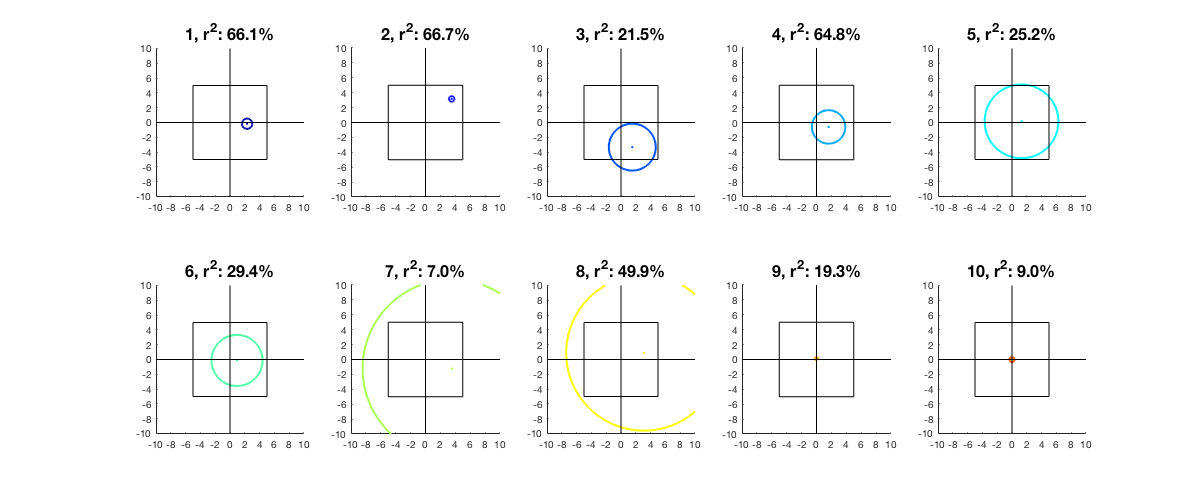

% Visualize the location of each voxel's pRF in a separate subplot
figure; hold on;
set(gcf,'Units','points','Position',[100 100 1200 500]);
cmap = jet(size(results.ang,1));
for p=1:size(results.ang,1)
    subplot(2,5,p)
    xpos = results.ecc(p) * cos(results.ang(p)/180*pi) * cfactor;
    ypos = results.ecc(p) * sin(results.ang(p)/180*pi) * cfactor;
    ang = results.ang(p)/180*pi;
    sd = results.rfsize(p) * cfactor;
    h = drawellipse(xpos,ypos,ang,2*sd,2*sd);  % circle at +/- 2 pRF sizes
    set(h,'Color',cmap(p,:),'LineWidth',2);
    set(scatter(xpos,ypos,'r.'),'CData',cmap(p,:));
    drawrectangle(0,0,10,10,'k-');  % square indicating stimulus extent
    axis([-10 10 -10 10]);
    straightline(0,'h','k-');       % line indicating horizontal meridian
    straightline(0,'v','k-');       % line indicating vertical meridian
    axis square;
    set(gca,'XTick',-10:2:10,'YTick',-10:2:10);
    %xlabel('X-position (deg)');
    %ylabel('Y-position (deg)');
    title(sprintf('%d, r^2: %3.1f%%', p, results.R2(p)), 'FontSize', 16);
end

## Visualize the predicted and observed time series. First, some setup...

% Define some variables
res = [100 100];                    % row x column resolution of the stimuli
resmx = max(res);                     % maximum resolution (along any dimension)
hrf = results.options.hrf;          % HRF that was used in the model
degs = results.options.maxpolydeg;  % vector of maximum polynomial degrees used in the model

% Pre-compute cache for faster execution
[d,xx,yy] = makegaussian2d(resmx,2,2,2,2);

% Prepare the stimuli for use in the model
stimulusPP = {};
for p=1:length(stimulus)
  stimulusPP{p} = squish(stimulus{p},2)';  % this flattens the image so that the dimensionality is now frames x pixels
  stimulusPP{p} = [stimulusPP{p} p*ones(size(stimulusPP{p},1),1)];  % this adds a dummy column to indicate run breaks
end

% Define the model function.  This function takes parameters and stimuli as input and
% returns a predicted time-series as output.  Specifically, the variable <pp> is a vector
% of parameter values (1 x 5) and the variable <dd> is a matrix with the stimuli (frames x pixels).
% Although it looks complex, what the function does is pretty straightforward: construct a
% 2D Gaussian, crop it to <res>, compute the dot-product between the stimuli and the
% Gaussian, raise the result to an exponent, and then convolve the result with the HRF,
% taking care to not bleed over run boundaries.
modelfun = @(pp,dd) conv2run(posrect(pp(4)) * (dd*[vflatten(placematrix(zeros(res),makegaussian2d(resmx,pp(1),pp(2),abs(pp(3)),abs(pp(3)),xx,yy,0,0) / (2*pi*abs(pp(3))^2))); 0]) .^ posrect(pp(5)),hrf,dd(:,prod(res)+1));

% Construct projection matrices that fit and remove the polynomials.
% Note that a separate projection matrix is constructed for each run.
polymatrix = {};
for p=1:length(degs)
  polymatrix{p} = projectionmatrix(constructpolynomialmatrix(size(data{p},2),0:degs(p)));
end

## Inspect the data and the model fit

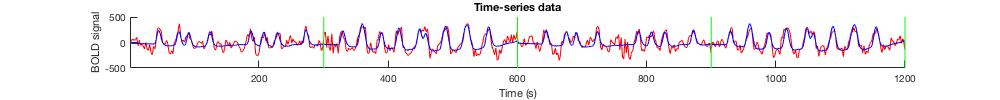

% Which voxel should we inspect?  Let's inspect the second voxel.
vx = 2;

% For each run, collect the data and the model fit.  We project out polynomials
% from both the data and the model fit.  This deals with the problem of
% slow trends in the data.
datats = {};
modelts = {};
for p=1:length(data)
  datats{p} =  polymatrix{p}*data{p}(vx,:)';
  modelts{p} = polymatrix{p}*modelfun(results.params(1,:,vx),stimulusPP{p});
end

% Visualize the results
figure; hold on;
set(gcf,'Units','points','Position',[100 100 1000 100]);
plot(cat(1,datats{:}),'r-');
plot(cat(1,modelts{:}),'b-');
straightline(300*(1:4)+.5,'v','g-');
xlabel('Time (s)');
ylabel('BOLD signal');
ax = axis;
axis([.5 1200+.5 ax(3:4)]);
title('Time-series data');

## Compare the prediction of the model to a different a temporally shuffled stimulus

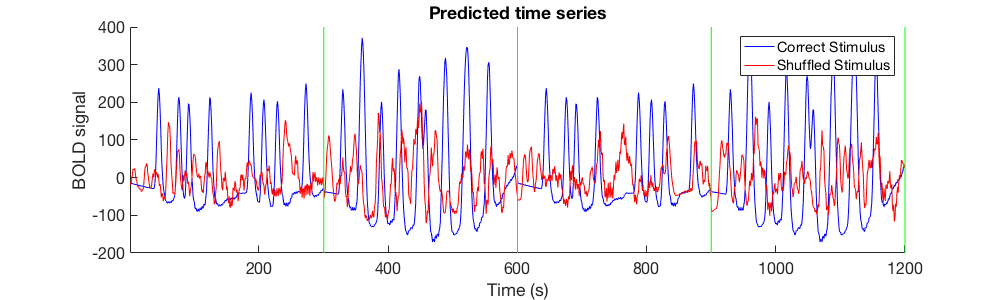

for p=1:length(data)
    n = size(data{p},2);
    idx = randperm(n);    
    modeltsShuffled{p} = polymatrix{p}*modelfun(results.params(1,:,vx),stimulusPP{p}(idx,:));
end

% Visualize the results
figure; hold on;
set(gcf,'Units','points','Position',[100 100 1000 300]);
plot(cat(1,modelts{:}),'b-');
plot(cat(1,modeltsShuffled{:}),'r-');
straightline(300*(1:4)+.5,'v','g-');
xlabel('Time (s)');
ylabel('BOLD signal');
ax = axis;
axis([.5 1200+.5 ax(3:4)]);
legend('Correct Stimulus', 'Shuffled Stimulus')
title('Predicted time series');
set(gca, 'FontSize', 16)

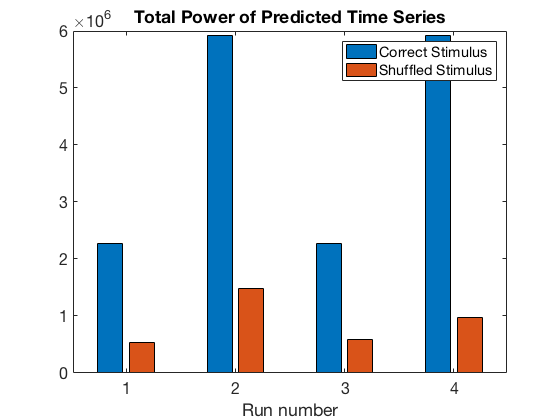


figure, bar(cellfun(@(x) sum(x.^2), [modelts; modeltsShuffled]'))
legend('Correct Stimulus', 'Shuffled Stimulus')
title('Total Power of Predicted Time Series')
xlabel('Run number')
set(gca, 'FontSize', 16)